# Asesoria Metodos numericos

### Asesoria 07/06/2022

clear
syms f(x) g(t)

f(x) = exp(-x) / x^2.4;
g(t) = f(1/t) * 1/t^2

$$g(t) = \frac{{\mathrm{e}}^{-\frac{1}{t}}}{t^{2}\,{\left(\frac{1}{t}\right)}^{12/5}}$$

g = matlabFunction(g);
f = matlabFunction(f);

I = GaussLegendre(g, 0, 1/1.9, 3)

I = 0.0157

I = integral(f, 1.9, inf)

I = 0.0158

clear
syms f(t, y)

f(t, y) = (t - 3)* exp(-t) * sin(y) + 1;
df(t, y) = diff(f, y)

$$df(t, y) = {\mathrm{e}}^{-t}\,\cos\left(y\right)\,\left(t-3\right)$$

df2(t) = df(t, pi)

$$df2(t) = -{\mathrm{e}}^{-t}\,\left(t-3\right)$$

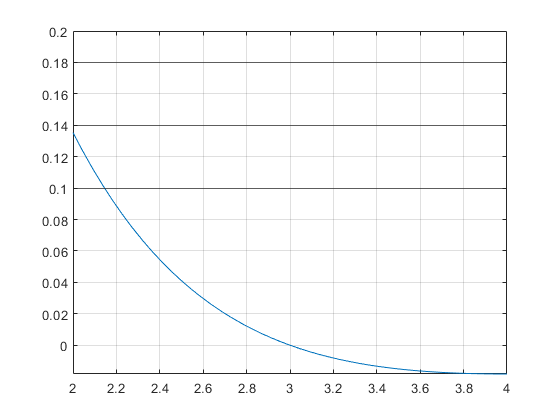

clf('reset')
fplot(df2, [2, 4])
yline(.1)
yline(.14)
yline(.2)
yline(.18)
grid on

f = matlabFunction(f);

EM = eulerMod(f,2, 4, 0, (4 - 2)/.1)

EM =     2.0000         0
    2.1000    0.0994
    2.2000    0.1980
    2.3000    0.2961
    2.4000    0.3941
    2.5000    0.4920
    2.6000    0.5903
    2.7000    0.6888
    2.8000    0.7877
    2.9000    0.8871


EM(EM == 3, :)

ans =     3.0000    0.9869


***Asesoria con cita: 06/08***

clear

f = @(x) - 1 ./ (x .* (x - 1) .* (x - 3));
g = @(t) f(1 ./ t) * 1./t.^2;
I1 = GaussLegendre(f, -1, 0, 10);
I2 = GaussLegendre(f, 0, 1, 10);
I3 = GaussLegendre(f, 1, 3, 10);
I4 = GaussLegendre(g, 0, 1/3, 10);

I = I1 + I2 + I3 + I4

I = -0.3945

Respuesta punto 1 $f\left(x\right)$.

***Asesoria Taller 06/08***

clear
syms A C f(x) x_1

% Grado 0
f(x) = 1;
df(x) = diff(f, x); % Derivada
I = int(f, -1, 4); % Integral
Eq0 = I == A*f(-1) + 2*df(x_1) + C*f(4) % Ecuaciones de grado n

$$Eq0 = 5=A+C$$

% Grado 1
f(x) = x;
df(x) = diff(f, x);
I = int(f, -1, 4);
Eq1 = I == A*f(-1) + 2*df(x_1) + C*f(4)

$$Eq1 = \frac{15}{2}=4\,C-A+2$$

% Grado 2
f(x) = x^2;
df(x) = diff(f, x);
I = int(f, -1, 4);
Eq2 = I == A*f(-1) + 2*df(x_1) + C*f(4)

$$Eq2 = \frac{65}{3}=A+16\,C+4\,x_{1}$$

S = solve(Eq0, Eq1, Eq2)

S = struct with fields:
      A: [1×1 sym]
      C: [1×1 sym]
    x_1: [1×1 sym]


A = eval(S.A), C = eval(S.C), x_1 = eval(S.x_1)

A = 2.9000

C = 2.1000

x_1 = -3.7083

clear
format short
syms f(t, y)

f(t, y) = 4*y - cos(t) - exp(t) - t % Función = y'

$$f(t, y) = 4\,y-t-\cos\left(t\right)-{\mathrm{e}}^{t}$$

df(t, y) = diff(f, t) + f(t, y) * diff(f, y); % Derivada = y''
d2f(t, y) = diff(df,t) + df(t, y) * diff(df, y); % y'''

df(t, y) = [f, df, d2f, 0]; %% USO DE TAYLOR 3

df = matlabFunction(df);
a = 0; b = 1; ya = 0; M = 40;

T4 = taylor(df, a, b, ya, M);
T4 

T4 =          0         0
    0.0250   -0.0536
    0.0500   -0.1141
    0.0750   -0.1824
    0.1000   -0.2592
    0.1250   -0.3454
    0.1500   -0.4421
    0.1750   -0.5503
    0.2000   -0.6713
    0.2250   -0.8064


solexac= @(t) (1/816)*(204*t + 272*exp(t) - 515*exp(4*t) - 48*sin(t) + 192*cos(t) + 51);
Valorexac = solexac(0.8)

Valorexac = -14.3571

Valoraprox = T4(T4 == 0.8, 2) 

Valoraprox = -14.5843

ErrR=(abs((Valoraprox-Valorexac)/Valorexac)) 

ErrR = 0.0158

### Asesoria 10/05/2022

`No se aprovecha el espacio de asesoria.`